clc,clear,close all

syms x y gamma
gamma = 1.4;
rho = 1+0.2 * sin(pi*(x+y));
u = 0.7;
v = 0.3;
p = 1;

% syms gamma rho u v p



% gamma = 1.4;
% rho = 1;
% u = 0.7;
% v = 0.3;
% p = 1;

u1 = rho

$$u1 = \frac{\sin\left(\pi \,\left(x+y\right)\right)}{5}+1$$

u2 = rho * u

$$u2 = \frac{7\,\sin\left(\pi \,\left(x+y\right)\right)}{50}+\frac{7}{10}$$

u3 = rho * v

$$u3 = \frac{3\,\sin\left(\pi \,\left(x+y\right)\right)}{50}+\frac{3}{10}$$

u4 = p / (gamma - 1) + 0.5 * rho * (u * u + v * v)

$$u4 = \frac{29\,\sin\left(\pi \,\left(x+y\right)\right)}{500}+\frac{279}{100}$$




E = u4;
c = sqrt(gamma * p / rho);
H = (E + p) / rho;
B1 = (gamma - 1) / c^2;
B2 = B1 * (u^2 + v^2) / 2;
uu = [u1,u2,u3,u4].';
duu = diff(uu,1);

eigMatrixR = [1,0,1,1
    u - c,0,u,u + c
    v,-1,v,v
    H - c * u,-v,(u^2 + v^2) / 2,H + c * u];

eigMatrixL = [
  (B2 + u / c) / 2,   -(B1 * u + 1.0 / c) / 2,  -(B1 * v) / 2,  B1 / 2;
  v,                  0,                        -1,             0;
  (1 - B2),           B1 * u,                   B1 * v,         -B1;
  (B2 - u / c) / 2,   -(B1 * u - 1.0 / c) / 2,  -B1 * v / 2,   B1 / 2
];

eigMatrixR = [1,0,1,1
    u - c,0,u,u + c
    v,-1,v,v
    H - c * u,-v,(u^2 + v^2) / 2,H + c * u];

eigMatrixL = [
  (B2 + u / c) / 2,   -(B1 * u + 1.0 / c) / 2,  -(B1 * v) / 2,  B1 / 2;
  v,                  0,                        -1,             0;
  (1 - B2),           B1 * u,                   B1 * v,         -B1;
  (B2 - u / c) / 2,   -(B1 * u - 1.0 / c) / 2,  -B1 * v / 2,   B1 / 2
];

## 投影并作图

### f(x)

f = eigMatrixL * uu;
f = matlabFunction(f(4))

f = 包含以下值的 function_handle :
    @(x,y)-(sin(pi.*(x+y)).*(7.0./5.0e+1)+7.0./1.0e+1).*(sin(pi.*(x+y))./5.0e+1-1.0./sqrt((7.0./5.0)./(sin(pi.*(x+y))./5.0+1.0))./2.0+1.0./1.0e+1)+(sin(pi.*(x+y))./5.0+1.0).*(sin(pi.*(x+y)).*8.285714285714286e-3-1.0./sqrt((7.0./5.0)./(sin(pi.*(x+y))./5.0+1.0)).*(7.0./2.0e+1)+2.9e+1./7.0e+2)-(sin(pi.*(x+y)).*(3.0./5.0e+1)+3.0./1.0e+1).*(sin(pi.*(x+y)).*(3.0./3.5e+2)+3.0./7.0e+1)+(sin(pi.*(x+y))./3.5e+1+1.0./7.0).*(sin(pi.*(x+y)).*(2.9e+1./5.0e+2)+2.79e+2./1.0e+2)


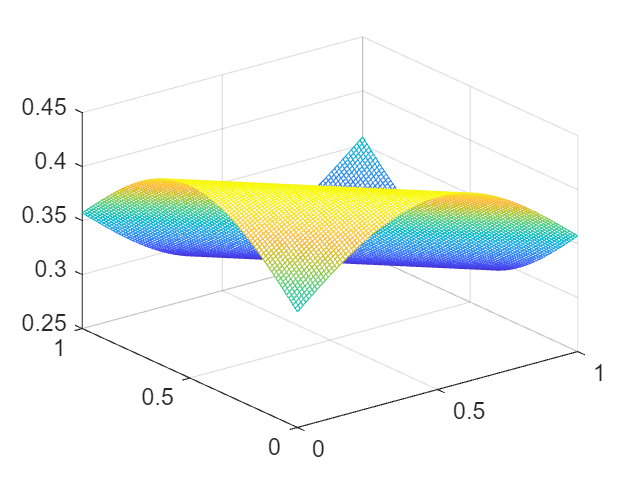


xx = 0:0.01:1;
yy = 0:0.01:1;
[X,Y] = meshgrid(xx,yy);
Z = f(X,Y);
mesh(X,Y,Z)

### df(x)

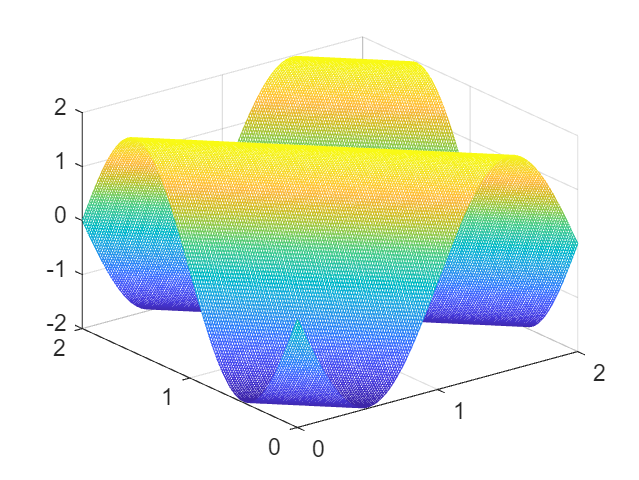

duu = diff(uu,x,2);

df = eigMatrixL * duu;
df = matlabFunction(df(3));
x = 0:0.01:2;
y = 0:0.01:2;
[X,Y] = meshgrid(x,y);
Z = df(X,Y);
mesh(X,Y,Z)